clc
clear


x=(0:0.1:1)';
t=(0:0.025:5)';
%Forcing2=Diff(Forcing1,2);
%ds=arrayDatastore([x,t,Forcing1]);
ValSize=256;
TrainSize=1024;
TestSize=256;
DLX=dlarray(zeros(2,TrainSize,length(t)),'CBT');
dlX=zeros(2,length(t)+10,TrainSize);
for i=1:TrainSize
    Amp1=rand(1)*1;
    Amp2=rand(1)*1;
    W1=rand(1)*pi*4;
    W2=rand(1)*pi*4;
    ddForcing1=Amp1*sin(W1*t);
    ddForcing2=Amp2*sin(W2*t);
    %%ddForcing1=diff(Forcing1,2)'/0.025^2;
    %%ddForcing2=diff(Forcing2,2)'/0.025^2;

    dlX(1,13:length(t)+12,i)=ddForcing1;
    dlX(2,13:length(t)+12,i)=ddForcing2;

    DLX(1,i,13:length(t)+12)=ddForcing1;
    DLX(2,i,13:length(t)+12)=ddForcing2;
end
DLX=gpuArray(DLX);

ValdlX=dlarray(zeros(2,ValSize,length(t)+10),'CBT');
for i=1:ValSize
    Amp1=rand(1)*1;
    Amp2=rand(1)*1;
    W1=rand(1)*pi*4;
    W2=rand(1)*pi*4;
    ddForcing1=Amp1*sin(W1*t);
    ddForcing2=Amp2*sin(W2*t);
    %ddForcing1=diff(Forcing1,2)'/0.025^2;
    %ddForcing2=diff(Forcing2,2)'/0.025^2;
    ValdlX(1,i,13:length(t)+12)=ddForcing1;
    ValdlX(2,i,13:length(t)+12)=ddForcing2;
end
ValdlX=gpuArray(ValdlX);
TestdlX=dlarray(zeros(2,TestSize,length(t)+10),'CBT');
for i=1:TestSize
    Amp1=rand(1)*1;
    Amp2=rand(1)*1;
    W1=rand(1)*pi*4;
    W2=rand(1)*pi*4;
    ddForcing1=Amp1*sin(W1*t);
    ddForcing2=Amp2*sin(W2*t);
    %ddForcing1=diff(Forcing1,2)'/0.025^2;
    %ddForcing2=diff(Forcing2,2)'/0.025^2;
    TestdlX(1,i,13:length(t)+12)=ddForcing1;
    TestdlX(2,i,13:length(t)+12)=ddForcing2;
end
TestdlX=gpuArray(TestdlX);
dsX = arrayDatastore(dlX,IterationDimension=3);


numHiddenUnits1 = 64;
numHiddenUnits2 = 128;
%custom low pass layer ekle
L2Fac=0.1;
poolSize=100;
layers = [ ...
    sequenceInputLayer(2,'Name','InputLayer','Normalization','none')
    fullyConnectedLayer(32,'Name','fcOut8','WeightsInitializer','glorot')
    reluLayer('Name','rel1')
    %lstmLayer(32,'Name','LSTM1')
    fullyConnectedLayer(32,'Name','fcOut1','WeightsInitializer','glorot')
    reluLayer('Name','rel2')
    fullyConnectedLayer(32,'Name','fcOut2','WeightsInitializer','glorot')
    reluLayer('Name','rel3')
    %lstmLayer(64,'Name','LSTM2')
    %fullyConnectedLayer(32,'Name','FC3','WeightsInitializer','he')
    %reluLayer('Name','rel4')
    %fullyConnectedLayer(32,'Name','FC4','WeightsInitializer','he')
    %reluLayer('Name','rel5')
    %fullyConnectedLayer(32,'Name','FC5','WeightsInitializer','he')
    %reluLayer('Name','rel6')
    %fullyConnectedLayer(32,'Name','FC6','WeightsInitializer','he')
    %reluLayer('Name','rel7')
    %lstmLayer(256,'Name','LSTM2','OutputMode','sequence')
    fullyConnectedLayer(20,'Name','fcOut3','WeightsInitializer','glorot')
    %convolution1dLayer(15,201,"Name",'Conv','Padding','same','PaddingValue','replicate')
    %reluLayer("Name",'Rel5')
    %convolution1dLayer(15,201,'Name','Conv5','Padding','same','PaddingValue','replicate')
    ];


% layers = [ ...
%     sequenceInputLayer(2,'Name','InputLayer')
%     convolution1dLayer(5,32,'Name','Conv1','Padding','same','PaddingValue',0)
%     reluLayer("Name",'Rel1')
%     convolution1dLayer(5,64,'Name','Conv2','Padding','same','PaddingValue',0)
%     reluLayer("Name",'Rel2')
%     convolution1dLayer(5,128,'Name','Conv3','Padding','same','PaddingValue',0)
%     reluLayer("Name",'Rel3')
%     convolution1dLayer(5,256,'Name','Conv4','Padding','same','PaddingValue',0)
%     reluLayer("Name",'Rel4')
%     convolution1dLayer(5,256,'Name','Conv5','Padding','same','PaddingValue',0)
%     reluLayer("Name",'Rel5')
%     convolution1dLayer(5,20,'Name','ConvOut','Padding','same','PaddingValue',0)
%     ];


View the network parameters.

lgraph = layerGraph(layers);

Create a `dlnetwork` object from the layer graph.

dlnet = dlnetwork(lgraph)

dlnet =   dlnetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
    Connections: [7×2 table]
     Learnables: [8×3 table]
          State: [0×3 table]
     InputNames: {'InputLayer'}
    OutputNames: {'fcOut3'}
    Initialized: 1

  View summary with summary.


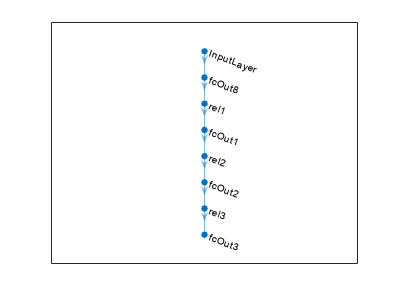


figure
plot(lgraph)

## Specify Training Options

numEpochs = 3500;
miniBatchSize = 1024;

initialLearnRate = 0.005;
decay = 0.0001;
mbq = minibatchqueue(dsX,...
    'MiniBatchSize',miniBatchSize,...
    'MiniBatchFormat',{'CTB'},OutputEnvironment='gpu');


## Train Model

Initialize the training progress plot.


figure
lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
lineLossTrain2 = animatedline('Color','b');
ylim([-inf inf])
xlabel("Iteration")
ylabel("Loss")
grid on

Train the network using a custom training loop. For each epoch, shuffle the data and loop over mini-batches of data. For each mini-batch:

- Evaluate the model gradients, state, and loss using the `dlfeval` and `modelGradients` functions and update the network state.

- Determine the learning rate for the time-based decay learning rate schedule.

- Update the network parameters using the `sgdmupdate` function.

- Display the training progress. 

iteration = 0;
start = tic;
averageGrad = [];
averageSqGrad = [];
%shuffle(mbq);
% Loop over epochs.
for epoch = 1:numEpochs
    % Shuffle data.
    shuffle(mbq);

    % Loop over mini-batches.
    while hasdata(mbq)
    %for i=1:length(Input)
    % Loop over mini-batches.

    iteration = iteration + 1;
             X= next(mbq);
    %         X = XTBC(1,:);
    %         T = XTBC(2,:);
    %         BC=XTBC(3,:);
    %dlX=INPUTS;
    % Read mini-batch of data.


    % Evaluate the model gradients, state, and loss using dlfeval and the
    % modelGradients function and update the network state.
    [gradients,state,loss] = dlfeval(@modelGradients,dlnet,X,miniBatchSize);
    dlnet.State = state;
    if mod(iteration,10)==1
        [~,~,Valloss] = dlfeval(@modelGradients,dlnet,ValdlX,ValSize);
        addpoints(lineLossTrain2,iteration,log10(Valloss)); hold on;drawnow
    end
    %         l2Regularization=0.001;
    %         idx = (dlnet.Learnables.Parameter == "Weights");
    %         idy = (dlnet.Learnables.Parameter == "Bias");
    %         gradients(idx,:)=dlupdate(@(g,w) g + l2Regularization*w, gradients(idx,:), dlnet.Learnables(idx,:));
    %         gradients(idy,:)=dlupdate(@(g,w) g + l2Regularization*w, gradients(idy,:), dlnet.Learnables(idy,:));
    % Determine learning rate for time-based decay learning rate schedule.
    learnRate = initialLearnRate/(1 + decay*iteration);

    % Update the network parameters using the SGDM optimizer.
    %[dlnet,velocity] = sgdmupdate(dlnet,gradients,velocity,learnRate,momentum);
    [dlnet,averageGrad,averageSqGrad] = adamupdate(dlnet,gradients,averageGrad,averageSqGrad,iteration,learnRate);
    %[dlnet,averageSqGrad] = rmspropupdate(dlnet,gradients,averageSqGrad,learnRate);
    % Display the training progress.

    addpoints(lineLossTrain,iteration,log10(loss)); hold on;drawnow
    D = duration(0,0,toc(start),'Format','hh:mm:ss');
    title("Epoch: " + epoch + ", Elapsed: " + string(D) + ", Loss: " + loss)

    end
end

disp('Train Data')

Train Data


%dlX=gpuArray(dlarray(dlX,'CTB'));
RND=ceil(rand(1)*(TrainSize));
[Dis] = predict(dlnet,DLX);
[~,~,Trainloss] = dlfeval(@modelGradients,dlnet,DLX,TrainSize)

Trainloss = 0.2655

TrainLOS=LF(dlnet,DLX,TrainSize)

TrainLOS =   1(C) × 6(B) × 1(T) single gpuArray dlarray

    0.0058    0.0058    0.0421    0.1041    0.0000         0


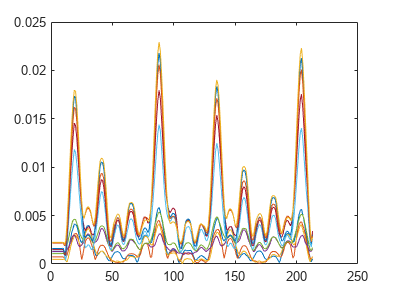

S=size(Dis);
v=Dis(1:S(1)/2,:,:);
w=Dis(S(1)/2+1:S(1),:,:);
%W=LinFilter(LinFilter(W,1),2);
W=double(gather(extractdata(LinFilter3(LinFilter2(w(:,RND,:))))));
V=double(gather(extractdata(LinFilter3(LinFilter2(v(:,RND,:))))));
S=size(W);
figure
Displacement=(reshape(W,10,S(3)).^2+reshape(V,10,S(3)).^2).^0.5;
plot(Displacement')

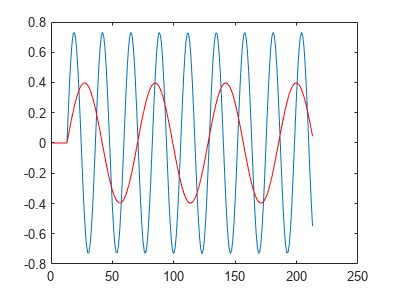

figure
plot(reshape(double(gather(extractdata(DLX(1,RND,:)))),1,[])');hold on;
plot(reshape(double(gather(extractdata(DLX(2,RND,:)))),1,[])','r')

% figure
% set(gcf,'Visible','on')
% for i=1:S(3)
%     plot3(1*W(:,i),1*V(:,i),0:0.1:0.9,'g','LineWidth',5);
%     box(0,0,0.001);grid minor
%     xlim([-0.002,0.002]);ylim([-0.002,0.002])
%     drawnow;
% 
%     title( sprintf('t = %.1f', (i-1)*0.025) )
%     hold all;
%     pause( 0.000000001 );hold off;
% end

disp('Val Data')

Val Data



RND=ceil(rand(1)*(ValSize-1));
[Dis] = predict(dlnet,ValdlX);
[~,~,Valloss] = dlfeval(@modelGradients,dlnet,ValdlX,ValSize)

Valloss = 0.2692

VALLLOS=LF(dlnet,ValdlX,ValSize)

VALLLOS =   1(C) × 6(B) × 1(T) single gpuArray dlarray

    0.0057    0.0057    0.0423    0.1015    0.0000         0


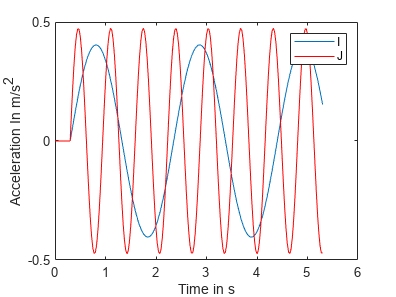

S=size(Dis);
v=Dis(1:S(1)/2,RND,:);
w=Dis(S(1)/2+1:S(1),RND,:);

figure
plot(0:0.025:5.3,reshape(double(gather(extractdata(ValdlX(1,RND,:)))),1,[])');hold on;
plot(0:0.025:5.3,reshape(double(gather(extractdata(ValdlX(2,RND,:)))),1,[])','r')
legend('I','J');xlabel('Time in s');ylabel('Acceleration In m/s^2');

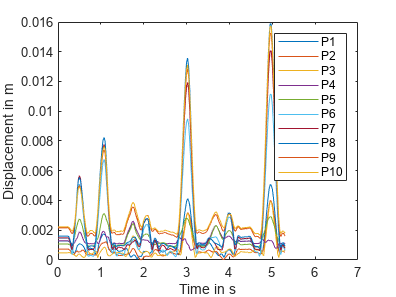

%W=LinFilter(LinFilter(W,1),2);
W=double(gather(extractdata(LinFilter3(LinFilter2(w(:,:,:))))));
V=double(gather(extractdata(LinFilter3(LinFilter2(v(:,:,:))))));

S=size(W);
figure
Displacement=(reshape(W,10,S(3)).^2+reshape(V,10,S(3)).^2).^0.5;
plot(0:0.025:5.3,Displacement');hold on;legend('P1','P2','P3','P4','P5','P6','P7','P8','P9','P10')
xlabel('Time in s');ylabel('Displacement in m');xlim([0 7]);

% figure
% set(gcf,'Visible','on')
% for i=1:S(3)
%     plot3(1*W(:,i),1*V(:,i),0:0.1:0.9,'g','LineWidth',5);
%     box(0,0,0.001);grid minor
%     xlim([-0.002,0.002]);ylim([-0.002,0.002])
%     drawnow;
% 
%     title( sprintf('t = %.1f', (i-1)*0.025) )
%     hold all;
%     pause( 0.000000001 );hold off;
% end


disp('Test Data')

Test Data


RND=ceil(rand(1)*(TestSize-1));
[Dis] = predict(dlnet,TestdlX);
[~,~,Testloss] = dlfeval(@modelGradients,dlnet,TestdlX,TestSize)

Testloss = 0.2796

TestLOS=LF(dlnet,TestdlX,TestSize)

TestLOS =   1(C) × 6(B) × 1(T) single gpuArray dlarray

    0.0061    0.0061    0.0460    0.1065    0.0000         0


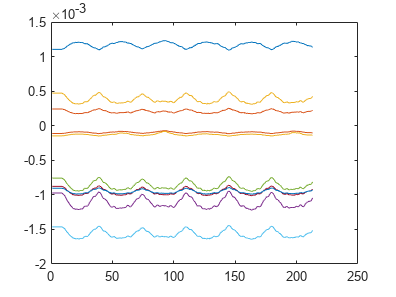

S=size(Dis);
v=Dis(1:S(1)/2,:,:);
w=Dis(S(1)/2+1:S(1),:,:);

%W=LinFilter(LinFilter(W,1),2);
W=double(gather(extractdata(LinFilter3(LinFilter2(w(:,RND,:))))));
V=double(gather(extractdata(LinFilter3(LinFilter2(v(:,RND,:))))));
S=size(W);
figure
plot(reshape(W,10,S(3))')

% figure
% set(gcf,'Visible','on')
% for i=1:S(3)
%     plot3(1*W(:,i),1*V(:,i),0:0.1:0.9,'g','LineWidth',5);
%     box(0,0,0.001);grid minor
%     xlim([-0.002,0.002]);ylim([-0.002,0.002])
%     drawnow;
% 
%     title( sprintf('t = %.1f', (i-1)*0.025) )
%     hold all;
%     pause( 0.000000001 );hold off;
% end



## Model Gradients Function

The `modelGradients` function takes a `dlnetwork` object `dlnet`, a mini-batch of input data `dlX` with corresponding labels `Y` and returns the gradients of the loss with respect to the learnable parameters in `dlnet`, the network state, and the loss. To compute the gradients automatically, use the `dlgradient` function.

function [gradients,state,loss] = modelGradients(dlnet,dlX,NumData)
Tstep=0.025;
Sstep=0.1;
[Dis,state] = forward(dlnet,dlX);
S=size(Dis);
v=Dis(1:S(1)/2,:,:);
w=Dis(S(1)/2+1:S(1),:,:);
W=LinFilter3(LinFilter2(w));
V=LinFilter3(LinFilter2(v));
S=size(W);

h=0.005;
b=0.005;
A=b*h;
I=b*h^3;
rho=1;
E=0.621*10^6;
Wx= (NDiff(W,1,Sstep));
Wt= (NDiff(W,2,Tstep));
Wtt= (NDiff(Wt,2,Tstep));
Wttx= (NDiff(Wtt,1,Sstep));
Wttxx= (NDiff(Wttx,1,Sstep));
Wxx= (NDiff(Wx,1,Sstep));
Wxxx= (NDiff(Wxx,1,Sstep));
Wxxxx= (NDiff(Wxxx,1,Sstep));

Vx= (NDiff(V,1,Sstep));
Vt= (NDiff(V,2,Tstep));
Vtt= (NDiff(Vt,2,Tstep));
Vttx= (NDiff(Vtt,1,Sstep));
Vttxx= (NDiff(Vttx,1,Sstep));
Vxx= (NDiff(Vx,1,Sstep));
Vxxx= (NDiff(Vxx,1,Sstep));
Vxxxx= (NDiff(Vxxx,1,Sstep));

R1=rho*A*dlX(1,:,:)+rho*A*Wtt+E*I*Vxxxx+I*E*Wxxxx-rho*I*(Vttxx+Wttxx);
R2=rho*A*dlX(2,:,:)+rho*A*Vtt+E*I*Vxxxx+I*E*Wxxxx-rho*I*(Vttxx+Wttxx);
BC1=sum(W(1,:,:).^2,'all')/NumData;
BC2=sum(Wx(1,:,:).^2,'all')/NumData;
BC3=sum(Wxx(S(1),:,:).^2,'all')/NumData;
BC4=sum(Wxxx(S(1),:,:).^2,'all')/NumData;

BC5=sum(V(1,:,:).^2,'all')/NumData;
BC6=sum(Vx(1,:,:).^2,'all')/NumData;
BC7=sum(Vxx(S(1),:,:).^2,'all')/NumData;
BC8=sum(Vxxx(S(1),:,:).^2,'all')/NumData;
zeroTarget = zeros(size(R1), 'like', R1);
L1=mse(R1,zeroTarget);
L2=mse(R2,zeroTarget);
IC1=sum(W(:,:,1).^2+V(:,:,1).^2,'all')/NumData;
IC2=sum(Wt(:,:,1).^2+Vt(:,:,1).^2,'all')/NumData;
loss=L1+L2+BC1+BC2+BC3+BC4+BC5+BC6+BC7+BC8+IC1+IC2;
Tloss=L1+L2+BC1*1000+BC2*10+BC3/10^3+BC4/10^5+BC5*1000+BC6*10+BC7/10^3+BC8/10^5+IC1*10000+IC2*10;
gradients = dlgradient(loss,dlnet.Learnables);


loss = double(gather(extractdata(loss)));

end


function LOSS=LF(dlnet,dlX,NumData)
Tstep=0.025;
Sstep=0.1;
[Dis,state] = forward(dlnet,dlX);
S=size(Dis);
v=Dis(1:S(1)/2,:,:);
w=Dis(S(1)/2+1:S(1),:,:);
W=LinFilter3(LinFilter2(w));
V=LinFilter3(LinFilter2(v));
S=size(W);

h=0.005;
b=0.005;
A=b*h;
I=b*h^3;
rho=1;
E=0.621*10^6;
Wx= (NDiff(W,1,Sstep));
Wt= (NDiff(W,2,Tstep));
Wtt= (NDiff(Wt,2,Tstep));
Wttx= (NDiff(Wtt,1,Sstep));
Wttxx= (NDiff(Wttx,1,Sstep));
Wxx= (NDiff(Wx,1,Sstep));
Wxxx= (NDiff(Wxx,1,Sstep));
Wxxxx= (NDiff(Wxxx,1,Sstep));

Vx= (NDiff(V,1,Sstep));
Vt= (NDiff(V,2,Tstep));
Vtt= (NDiff(Vt,2,Tstep));
Vttx= (NDiff(Vtt,1,Sstep));
Vttxx= (NDiff(Vttx,1,Sstep));
Vxx= (NDiff(Vx,1,Sstep));
Vxxx= (NDiff(Vxx,1,Sstep));
Vxxxx= (NDiff(Vxxx,1,Sstep));

R1=rho*A*dlX(1,:,:)+rho*A*Wtt+E*I*Vxxxx+I*E*Wxxxx-rho*I*(Vttxx+Wttxx);
R2=rho*A*dlX(2,:,:)+rho*A*Vtt+E*I*Vxxxx+I*E*Wxxxx-rho*I*(Vttxx+Wttxx);
BC1=sum(W(1,:,:).^2,'all')/NumData;
BC2=sum(Wx(1,:,:).^2,'all')/NumData;
BC3=sum(Wxx(S(1),:,:).^2,'all')/NumData;
BC4=sum(Wxxx(S(1),:,:).^2,'all')/NumData;

BC5=sum(V(1,:,:).^2,'all')/NumData;
BC6=sum(Vx(1,:,:).^2,'all')/NumData;
BC7=sum(Vxx(S(1),:,:).^2,'all')/NumData;
BC8=sum(Vxxx(S(1),:,:).^2,'all')/NumData;
zeroTarget = zeros(size(R1), 'like', R1);
L1=mse(R1,zeroTarget);
L2=mse(R2,zeroTarget);
IC1=sum(W(:,:,1).^2+V(:,:,1).^2,'all')/NumData;
IC2=sum(Wt(:,:,1).^2+Vt(:,:,1).^2,'all')/NumData;
LOSS=[L1,L2,BC1+BC2+BC3,BC4+BC5+BC5,IC1,IC2];
end



function dx=Diff(X,dim,Step)
S=size(X);
if dim==1
    X2=zeros(size(X),'like',X);
    X3=zeros(size(X),'like',X);
    X2(2:S(1),:,:)=X(1:S(1)-1,:,:);
    X2(1,:,:)=X(1,:,:);
    X3(1:S(1)-1,:,:)=X(2:S(1),:,:);
    X3(S(1),:,:)=X(S(1),:,:);
    dx=(X3-X2)/ Step/2;
    %dx(1,:,:)=(X3(1,:,:)-X(1,:,:))/Step;
    %dx(S(1),:,:)=(X(S(1),:,:)-X2(S(1),:,:))/Step;
else
X2=zeros(size(X),'like',X);
    X3=zeros(size(X),'like',X);
    X2(:,:,2:S(1))=X(:,:,1:S(1)-1);
    X2(:,:,1)=X(:,:,1);
    X3(:,:,1:S(1)-1)=X(:,:,2:S(1));
    X3(:,:,S(1))=X(:,:,S(1));
    dx=(X3-X2)/ Step/2;

end
end

function dx=NDiff(X,dim,Step)
S=size(X);
if dim==1
    X2=zeros(size(X),'like',X);
    X3=zeros(size(X),'like',X);
    X2(2:S(1),:,:)=X(1:S(1)-1,:,:);
    X2(1,:,:)=X(1,:,:);
    X3(1:S(1)-1,:,:)=X(2:S(1),:,:);
    X3(S(1),:,:)=X(S(1),:,:);
    dx=(X3-X2)/ Step/2;
    dx(1,:,:)=dx(2,:,:);
    dx(S(1),:,:)=dx(S(1)-1,:,:);
    ddx=Diff(dx,dim,Step);
    dx(1,:,:)=dx(2,:,:)-(ddx(2,:,:)+ddx(2,:,:)+ddx(2,:,:))/3* Step*2;
    dx(S(1),:,:)=dx(S(1)-1,:,:)+ddx(S(1)-1,:,:)* Step*2;
else
    X2=zeros(size(X),'like',X);
    X3=zeros(size(X),'like',X);
    X2(:,:,2:S(1))=X(:,:,1:S(1)-1);
    X2(:,:,1)=X(:,:,1);
    X3(:,:,1:S(1)-1)=X(:,:,2:S(1));
    X3(:,:,S(1))=X(:,:,S(1));
    dx=(X3-X2)/ Step/2;
    dx(:,:,1)=dx(:,:,2);
    dx(:,:,S(1))=dx(:,:,S(1)-1);
    ddx=Diff(dx,dim,Step);
    dx(:,:,1)=dx(:,:,2)-ddx(:,:,2)* Step*2;
    dx(:,:,S(1))=dx(:,:,S(1)-1)+ddx(:,:,S(1)-1)* Step*2;

end
end


function Y=LinFilter(X)
S=size(X);
X2=zeros(size(X),'like',X);
X2(2:S(1),:)=X(1:S(1)-1,:);
Y=(X+X2)/2;

end



function [RHO]=LinFilter2(X)
S=size(X);
L=S(1);
X1=(zeros(size(X),'like',X));
%X2=(zeros(size(X),'like',X));
X3=(zeros(size(X),'like',X));
% X4=(zeros(size(X),'like',X));
% X5=(zeros(size(X),'like',X));
% X6=(zeros(size(X),'like',X));
% X7=(zeros(size(X),'like',X));
% X8=(zeros(size(X),'like',X));
X1(2:L,:,:)=X(1:L-1,:,:);
X1(1,:,:)=X(1,:,:);
%X2(3:L,:)=X(1:L-2,:);
%X2(1:2,:)=X(1:2,:);
%X5(4:L,:)=X(1:L-3,:);
%X5(1:3,:)=X(1:3,:);
%X6(5:L,:)=X(1:L-4,:);
%X6(1:4,:)=X(1:4,:);



X3(1:L-1,:,:)=X( 2:L,:,:);
X3( L,:,:)=X( L,:,:);
%X4( 1:L-2,:)=X( 3:L,:);
%X4( L-1:L,:)=X( L-1:L,:);
%X7( 1:L-3,:)=X( 4:L,:);
%X7( L-2:L,:)=X( L-2:L,:);
%X8( 1:L-4,:)=X( 5:L,:);
%X8( L-3:L,:)=X( L-3:L,:);
%RHO=(X1+X2+X3+X4+X5+X6+X7+X8+X)/9;
RHO=(X+X1+X3)/3;
end


function [RHO]=LinFilter3(X)
S=size(X);
L=S(3);
X1=(zeros(size(X),'like',X));
X2=(zeros(size(X),'like',X));
X3=(zeros(size(X),'like',X));
X4=(zeros(size(X),'like',X));
X5=(zeros(size(X),'like',X));
X6=(zeros(size(X),'like',X));
X7=(zeros(size(X),'like',X));
X8=(zeros(size(X),'like',X));
X1(:,:,2:L)=X(:,:,1:L-1);
X1(:,:,1)=X(:,:,1);
X2(:,:,3:L)=X(:,:,1:L-2);
X2(:,:,1:2)=X(:,:,1:2);
X5(:,:,4:L)=X(:,:,1:L-3);
X5(:,:,1:3)=X(:,:,1:3);
X6(:,:,5:L)=X(:,:,1:L-4);
X6(:,:,1:4)=X(:,:,1:4);



X3(:,:,1:L-1)=X(:,:, 2:L);
X3(:,:, L)=X(:,:, L);
X4(:,:, 1:L-2)=X(:,:, 3:L);
X4(:,:, L-1:L)=X(:,:, L-1:L);
X7(:,:, 1:L-3)=X(:,:, 4:L);
X7(:,:, L-2:L)=X(:,:, L-2:L);
X8(:,:, 1:L-4)=X(:,:, 5:L);
X8(:,:, L-3:L)=X(:,:, L-3:L);
RHO=(X1+X2+X3+X4+X5+X6+X7+X8+X)/9;

end
function box(ax,ay,w)
% Center point is at coordinate [ax ay az].
%ax = 0;  ay = 0;

% Full-width of each side of cube.
%w = 0.01;

% For readability.
h = w;
az = -h;
patch_args = { 'FaceColor', 'b', 'FaceAlpha', 1 };

% Side #1 of 6.
patch( 'XData', ax+[-h -h  h  h], 'YData', ay+[-h  h  h -h], 'ZData', az+[-h -h -h -h], patch_args{:} )
%daspect( [1 1 1] )  % 1:1:1 aspect ratio.
%hold on
% Side #2 of 6.
patch( 'XData', ax+[-h -h  h  h], 'YData', ay+[-h  h  h -h], 'ZData', az+[ h  h  h  h], patch_args{:} )
% Side #3 of 6.
patch( 'XData', ax+[-h -h  h  h], 'YData', ay+[ h  h  h  h], 'ZData', az+[-h  h  h -h], patch_args{:} )
% Side #4 of 6.
patch( 'XData', ax+[-h -h  h  h], 'YData', ay+[-h -h -h -h], 'ZData', az+[-h  h  h -h], patch_args{:} )
% Side #5 of 6.
patch( 'XData', ax+[ h  h  h  h], 'YData', ay+[-h -h  h  h], 'ZData', az+[-h  h  h -h], patch_args{:} )
% Side #6 of 6.
patch( 'XData', ax+[-h -h -h -h], 'YData', ay+[-h -h  h  h], 'ZData', az+[-h  h  h -h], patch_args{:} )

% Red dot in middle.
%scatter3( ax, ay, az, 'or', 'filled', 'SizeData', 150 )

%hold off
end

*Copyright 2019 The MathWorks, Inc.*